# **Data wrangling sandbox**

### **Step 1: load necessary data and format it for later analysis **

**Goal 1: **Load in CaliAli matlab files with extracted neuron data arrays (in my case LT activity across 3 sessions)

**Goal 2: **Load in calcium and behavior recording software timestamp files and concatenate them to match frame length of CaliAli data (3 sessions)

**Goal 3: **Load in ezTrack location tracking files and do the same

% Define paths to your individual session CaliAli output files
session_mat_files = {
    'Z:\Ivan\MECIII_Ca_Imaging\data\summer_cohort_2021\SF37-0\customEntValHere\LTA_1_2021_08_04\13_48_40\Miniscope_2_con_mc_det_source_extraction\frames_1_17832\LOGS_13-Jun_10_54_02\16-Jun_11_30_06.mat',
    'Z:\Ivan\MECIII_Ca_Imaging\data\summer_cohort_2021\SF37-0\customEntValHere\LTA_2_2021_08_06\13_50_06\Miniscope_2_con_mc_det_source_extraction\frames_1_17832\LOGS_23-May_11_32_03\23-May_13_50_56.mat',
    'Z:\Ivan\MECIII_Ca_Imaging\data\summer_cohort_2021\SF37-0\customEntValHere\LTA_3_2021_08_08\14_52_12\Miniscope_2_con_mc_det_source_extraction\frames_1_17830\LOGS_23-May_14_12_05\23-May_16_01_49.mat'
    };

% Define timestamp and ezTrack location tracking file paths
Miniscope_timestamp_files = {
    'Z:\Ivan\MECIII_Ca_Imaging\data\summer_cohort_2021\SF37-0\customEntValHere\LTA_1_2021_08_04\13_48_40\Miniscope_2\timeStamps.csv',
    'Z:\Ivan\MECIII_Ca_Imaging\data\summer_cohort_2021\SF37-0\customEntValHere\LTA_2_2021_08_06\13_50_06\Miniscope_2\timeStamps.csv',
    'Z:\Ivan\MECIII_Ca_Imaging\data\summer_cohort_2021\SF37-0\customEntValHere\LTA_3_2021_08_08\14_52_12\Miniscope_2\timeStamps.csv'
    };

Behavior_timestamp_files = {
    'Z:\Ivan\MECIII_Ca_Imaging\data\summer_cohort_2021\SF37-0\customEntValHere\LTA_1_2021_08_04\13_48_40\BehavCam_0\timeStamps.csv',
    'Z:\Ivan\MECIII_Ca_Imaging\data\summer_cohort_2021\SF37-0\customEntValHere\LTA_2_2021_08_06\13_50_06\BehavCam_0\timeStamps.csv',
    'Z:\Ivan\MECIII_Ca_Imaging\data\summer_cohort_2021\SF37-0\customEntValHere\LTA_3_2021_08_08\14_52_12\BehavCam_0\timeStamps.csv'
    };

ezTrackfiles = {
    'Z:\Ivan\MECIII_Ca_Imaging\data\summer_cohort_2021\SF37-0\customEntValHere\LTA_1_2021_08_04\13_48_40\BehavCam_0\SF37-0_LT1_Merged_LocationOutput.csv',
    'Z:\Ivan\MECIII_Ca_Imaging\data\summer_cohort_2021\SF37-0\customEntValHere\LTA_2_2021_08_06\13_50_06\BehavCam_0\SF37-0_LT2_Merged_LocationOutput.csv',
    'Z:\Ivan\MECIII_Ca_Imaging\data\summer_cohort_2021\SF37-0\customEntValHere\LTA_3_2021_08_08\14_52_12\BehavCam_0\SF37-0_LT3_Merged_LocationOutput.csv'
    };

% Load multiple CaliAli output files
fprintf('=== Loading CaliAli Output Files ===\n');

=== Loading CaliAli Output Files ===


session_neurons = cell(1, length(session_mat_files));
for s = 1:length(session_mat_files)
    fprintf('Loading session %d: %s\n', s, session_mat_files{s});

    % *** Check that file exists ***
    if ~exist(session_mat_files{s}, 'file')
        error('File not found: %s', session_mat_files{s});
    end

    temp = load(session_mat_files{s});

    % *** Check if neuron variable exists ***
    if ~isfield(temp, 'neuron')
        error('No "neuron" variable found in %s', session_mat_files{s});
    end

    session_neurons{s} = temp.neuron;
    fprintf('  → %d neurons, %d frames\n', size(temp.neuron.S, 1), size(temp.neuron.S, 2));
end

Loading session 1: Z:\Ivan\MECIII_Ca_Imaging\data\summer_cohort_2021\SF37-0\customEntValHere\LTA_1_2021_08_04\13_48_40\Miniscope_2_con_mc_det_source_extraction\frames_1_17832\LOGS_13-Jun_10_54_02\16-Jun_11_30_06.mat


  → 18 neurons, 17832 frames


Loading session 2: Z:\Ivan\MECIII_Ca_Imaging\data\summer_cohort_2021\SF37-0\customEntValHere\LTA_2_2021_08_06\13_50_06\Miniscope_2_con_mc_det_source_extraction\frames_1_17832\LOGS_23-May_11_32_03\23-May_13_50_56.mat


  → 21 neurons, 17832 frames


Loading session 3: Z:\Ivan\MECIII_Ca_Imaging\data\summer_cohort_2021\SF37-0\customEntValHere\LTA_3_2021_08_08\14_52_12\Miniscope_2_con_mc_det_source_extraction\frames_1_17830\LOGS_23-May_14_12_05\23-May_16_01_49.mat


  → 13 neurons, 17830 frames



% Process timestamps and position data for each session
fprintf('\n=== Processing Timestamps and Position Data ===\n');


=== Processing Timestamps and Position Data ===


all_cal_timestamps = cell(1, 3);
all_beh_timestamps = cell(1, 3);
all_X_scaled_matched = cell(1, 3);

track_length = 200; % 2m in cm

for s = 1:3
    fprintf('Processing session %d timestamps...\n', s);

    % *** Check that timestamp files exist ***
    if ~exist(Miniscope_timestamp_files{s}, 'file')
        error('Calcium timestamp file not found: %s', Miniscope_timestamp_files{s});
    end
    if ~exist(Behavior_timestamp_files{s}, 'file')
        error('Behavior timestamp file not found: %s', Behavior_timestamp_files{s});
    end

    % Load timestamps for this session
    cal_ts_table = readtable(Miniscope_timestamp_files{s});
    beh_ts_table = readtable(Behavior_timestamp_files{s});

    % *** Check actual column names
    fprintf('Calcium timestamp columns: ');
    disp(cal_ts_table.Properties.VariableNames);
    fprintf('Behavior timestamp columns: ');
    disp(beh_ts_table.Properties.VariableNames);

    % *** Check that expected columns exist ***
    if ~ismember('TimeStamp_ms_', cal_ts_table.Properties.VariableNames)
        error('TimeStamp_ms_ column not found in calcium timestamps for session %d', s);
    end

    % Match calcium to behavior timestamps
    matched_behavior_idx = zeros(height(cal_ts_table), 1);
    cal_ts = cal_ts_table.TimeStamp_ms_;
    beh_ts = beh_ts_table.TimeStamp_ms_;

    for i = 1:length(cal_ts)
        [~, rel_idx] = min(abs(beh_ts - cal_ts(i)));
        matched_behavior_idx(i) = rel_idx;
    end

    % *** Check that ezTrack file exists ***
    if ~exist(ezTrackfiles{s}, 'file')
        error('ezTrack file not found: %s', ezTrackfiles{s});
    end

    % Load and scale position data
    P = readtable(ezTrackfiles{s});

    % *** Check that X column exists ***
    if ~ismember('X', P.Properties.VariableNames)
        error('X column not found in ezTrack data for session %d', s);
    end

    X_pos = P.X;
    min_X = min(X_pos);
    max_X = max(X_pos);
    X_scaled = (X_pos - min_X) / (max_X - min_X) * track_length;

    % Extract matched position data
    X_scaled_matched_session = X_scaled(matched_behavior_idx);

    % Store data for this session
    all_cal_timestamps{s} = cal_ts_table;
    all_beh_timestamps{s} = beh_ts_table;
    all_X_scaled_matched{s} = X_scaled_matched_session;

    % Add session labels
    all_cal_timestamps{s}.Session = repmat(s, height(cal_ts_table), 1);
    all_beh_timestamps{s}.Session = repmat(s, height(beh_ts_table), 1);

    fprintf('  → %d matched frames (%.1f%% of calcium frames)\n', ...
        length(X_scaled_matched_session), ...
        100 * length(X_scaled_matched_session) / size(session_neurons{s}.S, 2));
end

Processing session 1 timestamps...


Calcium timestamp columns: 

    {'FrameNumber'}    {'TimeStamp_ms_'}    {'BufferIndex'}



Behavior timestamp columns: 

    {'FrameNumber'}    {'TimeStamp_ms_'}    {'BufferIndex'}



  → 17832 matched frames (100.0% of calcium frames)


Processing session 2 timestamps...


Calcium timestamp columns: 

    {'FrameNumber'}    {'TimeStamp_ms_'}    {'BufferIndex'}



Behavior timestamp columns: 

    {'FrameNumber'}    {'TimeStamp_ms_'}    {'BufferIndex'}



  → 17832 matched frames (100.0% of calcium frames)


Processing session 3 timestamps...


Calcium timestamp columns: 

    {'FrameNumber'}    {'TimeStamp_ms_'}    {'BufferIndex'}



Behavior timestamp columns: 

    {'FrameNumber'}    {'TimeStamp_ms_'}    {'BufferIndex'}



  → 17830 matched frames (100.0% of calcium frames)



% Concatenate data to maintain compatibility with existing analysis
fprintf('\n=== Concatenating Session Data ===\n');


=== Concatenating Session Data ===



% Concatenate timestamps (for compatibility with existing code)
cal_timestamp_early = vertcat(all_cal_timestamps{:});
beh_timestamp_early = vertcat(all_beh_timestamps{:});
X_scaled_matched = vertcat(all_X_scaled_matched{:});

% Keep neuron data separate by session
neuron_sessions = session_neurons; % keep original session structure

% Create a "pseudoconcatenated" structure for compatibility
neuron = struct();
neuron.session_data = session_neurons; % store individual sessions
neuron.n_sessions = length(session_neurons);

% Create session frame indices for easy access
neuron.session_frame_idx = cell(1, length(session_neurons));
cumulative_frames = 0;
for s = 1:length(session_neurons)
    n_frames = size(session_neurons{s}.S, 2);
    neuron.session_frame_idx{s} = (cumulative_frames + 1):(cumulative_frames + n_frames);
    cumulative_frames = cumulative_frames + n_frames;
    
    fprintf('Session %d: frames %d-%d, %d neurons\n', s, ...
        neuron.session_frame_idx{s}(1), neuron.session_frame_idx{s}(end), ...
        size(session_neurons{s}.S, 1));
end

Session 1: frames 1-17832, 18 neurons
Session 2: frames 17833-35664, 21 neurons
Session 3: frames 35665-53494, 13 neurons



fprintf('Neuron data kept separate by session\n');

Neuron data kept separate by session



% Final data validation
fprintf('\n=== Data Validation Summary ===\n');


=== Data Validation Summary ===


cumulative_frames = 0;
for s = 1:3
    n_calcium = size(session_neurons{s}.S, 2);
    n_position = length(all_X_scaled_matched{s});
    n_neurons = size(session_neurons{s}.S, 1);

    fprintf('Session %d:\n', s);
    fprintf('  Neurons: %d\n', n_neurons);
    fprintf('  Calcium frames: %d\n', n_calcium);
    fprintf('  Position frames: %d\n', n_position);
    fprintf('  Frame range in concatenated data: %d-%d\n', ...
        cumulative_frames + 1, cumulative_frames + n_calcium);

    % *** ADD CHECK: Verify frame counts match ***
    if n_calcium ~= n_position
        warning('Session %d: Calcium frames (%d) ≠ Position frames (%d)', s, n_calcium, n_position);
    end

    cumulative_frames = cumulative_frames + n_calcium;
end

Session 1:


  Neurons: 18


  Calcium frames: 17832


  Position frames: 17832


  Frame range in concatenated data: 1-17832


Session 2:


  Neurons: 21


  Calcium frames: 17832


  Position frames: 17832


  Frame range in concatenated data: 17833-35664


Session 3:


  Neurons: 13


  Calcium frames: 17830


  Position frames: 17830


  Frame range in concatenated data: 35665-53494



fprintf('\nConcatenated Data Summary:\n');


Concatenated Data Summary:


total_neurons_across_sessions = sum(cellfun(@(x) size(x.S, 1), neuron.session_data));
total_frames_across_sessions = sum(cellfun(@(x) size(x.S, 2), neuron.session_data));
neurons_per_session = cellfun(@(x) size(x.S, 1), neuron.session_data);

fprintf('  Total neurons across all sessions: %d\n', total_neurons_across_sessions);

  Total neurons across all sessions: 52


fprintf('  Neurons per session: %s\n', num2str(neurons_per_session));

  Neurons per session: 18  21  13


fprintf('  Total frames: %d\n', total_frames_across_sessions);

  Total frames: 53494


fprintf('  Total position points: %d\n', length(X_scaled_matched));

  Total position points: 53494


fprintf('  Session labels: %d unique sessions\n', length(unique(cal_timestamp_early.Session)));

  Session labels: 3 unique sessions


# **Create LT neural activity rate maps**

### **Step 2: Visualize spatial rate maps across sessions**

**Goal 1: **Divide linear track into spatial segments

**Goal 2: **Set velocity and directionality thresholds

**Goal 3: **Compute occupancy and neuron activity per bin and smooth data

**Goal 4: **Compute spatial activity rate and sort neurons by peak bin

**Goal 5: **Visualize spatial rate heat map


=== Analyzing Session 1 Rate Maps ===


Session had 1404 rightward frames, 1581 leftward frames


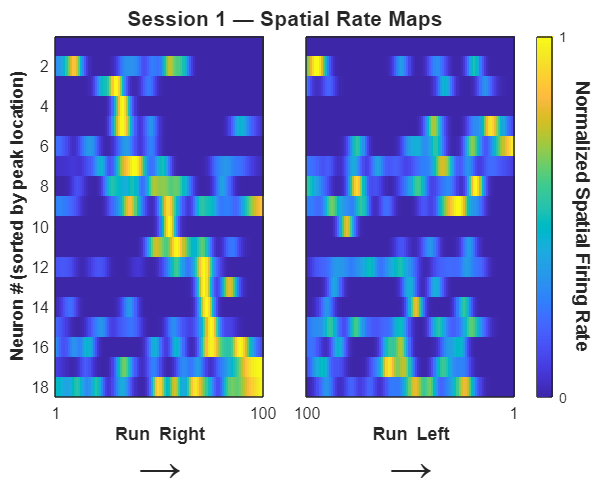


=== Analyzing Session 2 Rate Maps ===


Session had 1439 rightward frames, 1674 leftward frames


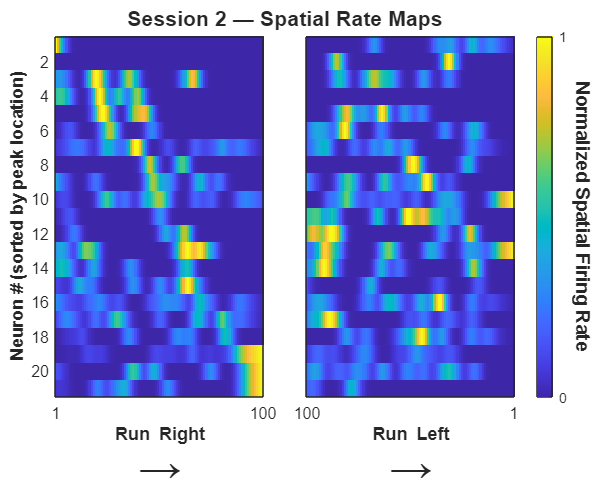


=== Analyzing Session 3 Rate Maps ===


Session had 1352 rightward frames, 1245 leftward frames


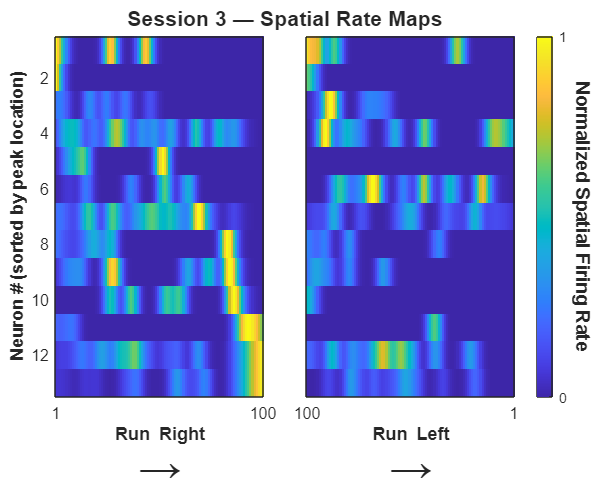

params = struct( ...
    'track_length', 200, ...
    'bin_size_cm', 8, ...
    'frame_rate', 15, ...
    'velocity_thresh', 10, ... % was 10 in Shuman et al.
    'smoothing_sigma_cm', 8); % was 5 in Shuman et al.

% Loop over sessions and analyze each separately
sessions = unique(cal_timestamp_early.Session);
all_session_results = struct();

for s = 1:length(sessions)
    fprintf('\n=== Analyzing Session %d Rate Maps ===\n', s);

    session_mask = cal_timestamp_early.Session == sessions(s);
    session_neuron_S = neuron_sessions{s}.S;

    % Compute maps using corrected session specific data
    [rate_map_left_sorted, rate_map_right_sorted, ...
        rate_map_left, rate_map_right, ...
        smooth_occ_left, smooth_occ_right] = ...
        compute_spatial_rate_maps_corrected(X_scaled_matched, session_neuron_S, session_mask, params);

    % Plot maps
    plot_spatial_rate_maps_for_session(rate_map_right_sorted, ...
        rate_map_left_sorted, ...
        sessions(s));
end

# **Create spatial spike rasters**

### **Step 3: Track per trial neural activity across spatial bins**

**Goal 1: **Track laps in each way and verify with behavior notes

**Goal 2: **Plot spatial rasters for neuron spike events across bins


=== Analyzing Session 1 Spike Rasters ===


Detected 18 rightward laps, 18 lefrward laps


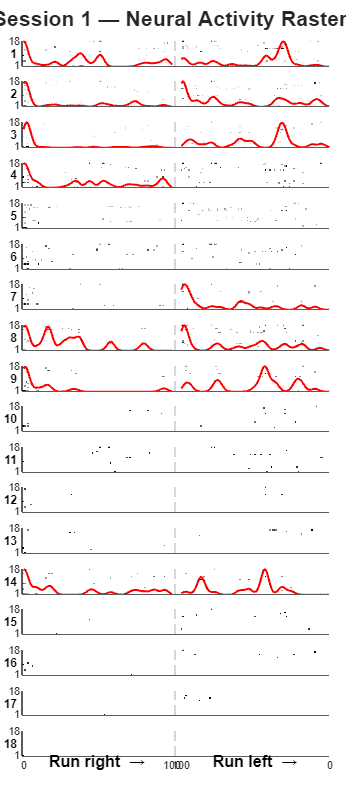


=== Analyzing Session 2 Spike Rasters ===


Detected 17 rightward laps, 17 lefrward laps


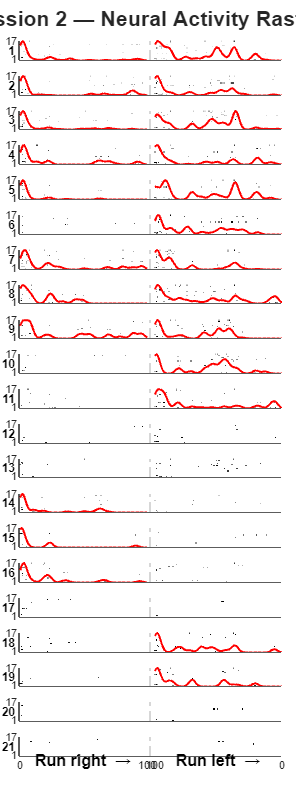


=== Analyzing Session 3 Spike Rasters ===


Detected 15 rightward laps, 15 lefrward laps


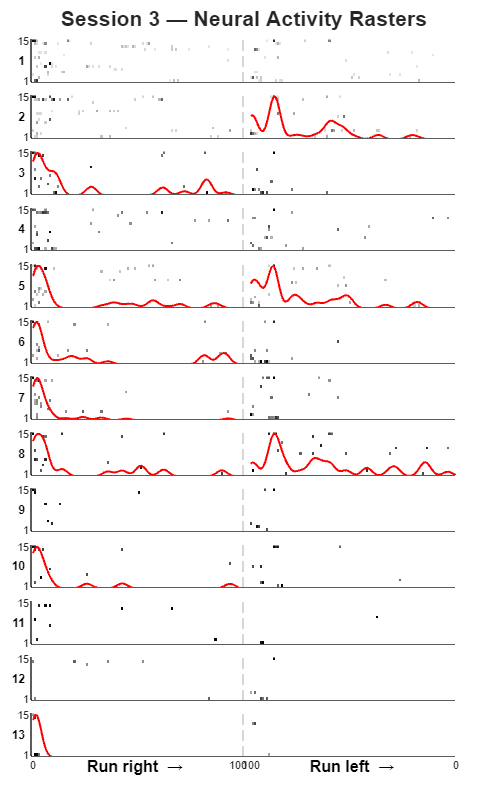

% Loop over sessions
for s = 1:length(sessions)
    fprintf('\n=== Analyzing Session %d Spike Rasters ===\n', s);

    session_mask = cal_timestamp_early.Session == sessions(s); % session specific mask

    % Get session specific neuron data
    session_neuron_S = neuron_sessions{s}.S;

    % Compute rasters using session-specific data
    [lap_spike_raster_right, lap_spike_raster_left, gaussian_kernel] = ...
        compute_spike_rasters(X_scaled_matched, session_neuron_S, session_mask, params);
    % Plot rasters
    plot_spike_rasters_for_session(lap_spike_raster_right, ...
        lap_spike_raster_left, ...
        gaussian_kernel, ...
        sessions(s));
end

# **Calculate information content of the spatial neural activity rate map**

### **Step 4: Calculate the Skaggs information content of each cell u**sing the Shuman et al. (2020) formula

**Goal 1: **Calculate information content

**Goal 2: **Circularly shuffle trial occupancy and neural activity data by random amounts 500 times

**Goal 3**: Compare data distributions of information content to shuffled distributions

### 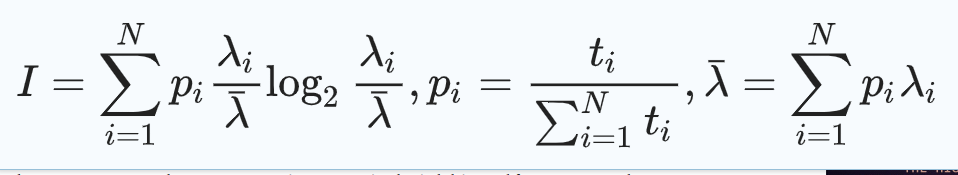

### 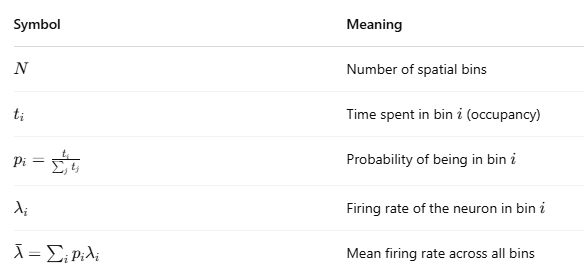

*"...where ti represents the occupancy time spent in the i-th bin and λi represents the neural activity rate in the i-th bin. The significance of the spatial information was calculated using a circular trial shuffling procedure. For each trial, the position of the animal was circularly shifted by a random amount and then the spatial activity rate map and information content was calculated across all shuffled trials. This procedure was repeated 500 times to determine a significance measure for the spatial activity rate map of each neuron. The significance measure is the percentile of the true information content value within the distribution of the information content values from the 500 randomly shuffled sessions."*

% Initialize results storage for all sessions
sessions = unique(cal_timestamp_early.Session); 
all_session_results = struct();

% Loop over sessions
for s = 1:length(sessions)
    fprintf('\n=== Calculating Info Content for Session %d ===\n', s);

    session_mask = cal_timestamp_early.Session == sessions(s); 
    session_neuron_S = neuron_sessions{s}.S;

    % Compute spatial rate maps for the left and right trajectories
    % This gives firing rates across spatial bins and occupancy information
    [rate_map_left_sorted, rate_map_right_sorted, ...
        rate_map_left, rate_map_right, ...
        smooth_occ_left, smooth_occ_right] = ...
        compute_spatial_rate_maps_corrected(X_scaled_matched, session_neuron_S, session_mask, params);

    % Get number of bins from rate map size
    num_bins = size(rate_map_right, 2);

    % calculate spatial information content separately for right and left directions
    info_right = compute_spatial_info_corrected(rate_map_right, smooth_occ_right);
    info_left  = compute_spatial_info_corrected(rate_map_left, smooth_occ_left);

    % get total time spent in each direction for potential weighted averaging
    total_time_right = sum(smooth_occ_right);
    total_time_left = sum(smooth_occ_left);

    % calculate combined info content - weighted by time spent in each direction
    weights = [total_time_left, total_time_right] / (total_time_left + total_time_right);
    info_combined = weights(1) * info_left + weights(2) * info_right;

    % Perform circular shuffling (500 shuffles) using session specific data
    [info_right_shuffles, percentile_right, pval_right] = ...
        shuffle_spatial_info_corrected(X_scaled_matched(session_mask), ...
                            session_neuron_S, ...
                            params, ...
                            info_right, ...
                            'right', ...
                            num_bins, ...
                            500);

    [info_left_shuffles, percentile_left, pval_left] = ...
        shuffle_spatial_info_corrected(X_scaled_matched(session_mask), ...
                            session_neuron_S, ...
                            params, ...
                            info_left, ...
                            'left', ...
                            num_bins, ...
                            500);

    % Calculate weighted shuffled info for combined measure
    % Use same weights as for real data
    info_combined_shuffles = weights(1) * info_left_shuffles + weights(2) * info_right_shuffles;

    % Determine which cells are significant (using 90th percentile)
    sig_right = determine_significant_cells(info_right, info_right_shuffles, 90);
    sig_left = determine_significant_cells(info_left, info_left_shuffles, 90);
    sig_combined = determine_significant_cells(info_combined, info_combined_shuffles, 90);
    
    % Create structure to track stats across sessions
    all_session_results(s).session = sessions(s);
    all_session_results(s).n_neurons = size(session_neuron_S, 1);
    all_session_results(s).info_right = info_right;
    all_session_results(s).info_left = info_left;
    all_session_results(s).info_combined = info_combined;
    all_session_results(s).sig_combined = sig_combined;
    all_session_results(s).percent_significant = 100 * sum(sig_combined) / length(sig_combined);
    
    fprintf('Session %d: %d neurons, %.1f%% significant\n', s, ...
        all_session_results(s).n_neurons, ...
        all_session_results(s).percent_significant);
end


=== Calculating Info Content for Session 1 ===


Session had 1404 rightward frames, 1581 leftward frames


Performing 500 circular shuffles for right direction


Performing 500 circular shuffles for left direction


Session 1: 18 neurons, 5.6% significant



=== Calculating Info Content for Session 2 ===


Session had 1439 rightward frames, 1674 leftward frames


Performing 500 circular shuffles for right direction


Performing 500 circular shuffles for left direction


Session 2: 21 neurons, 4.8% significant



=== Calculating Info Content for Session 3 ===


Session had 1352 rightward frames, 1245 leftward frames


Performing 500 circular shuffles for right direction


Performing 500 circular shuffles for left direction


Session 3: 13 neurons, 0.0% significant


% Check data before visualization
fprintf('=== Debug Info Before Visualization ===\n');

=== Debug Info Before Visualization ===


fprintf('Number of sessions with results: %d\n', length(all_session_results));

Number of sessions with results: 3


for s = 1:length(all_session_results)
    fprintf('Session %d: %d neurons, max info = %.4f\n', s, ...
        all_session_results(s).n_neurons, ...
        max(all_session_results(s).info_combined));
end

Session 1: 18 neurons, max info = 3.2745
Session 2: 21 neurons, max info = 2.1938
Session 3: 13 neurons, max info = 2.9445



% Check if max_info calculation works
try
    max_info = max(cellfun(@(x) max(x(:)), {all_session_results.info_combined}));
    fprintf('Max info across all sessions: %.4f\n', max_info);
catch ME
    fprintf('Error calculating max_info: %s\n', ME.message);
    max_info = 2;  % Set a default value
end

Max info across all sessions: 3.2745


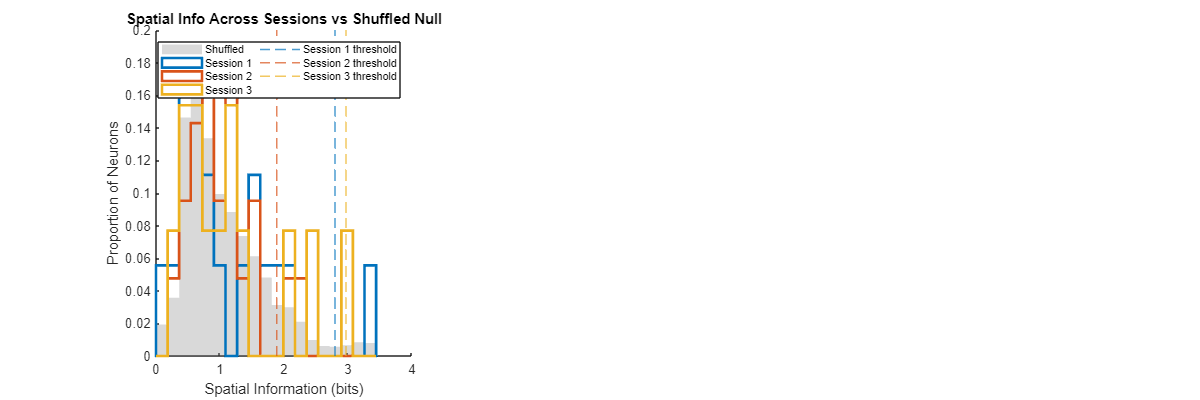



% Create visualization of results
figure ('Position', [100, 100, 1200, 400]);

% Get colors for sessions
colors = lines(length(all_session_results)); 

% Define common bin edges for consistent comparison
max_info = max(cellfun(@(x) max(x(:)), {all_session_results.info_combined}'));
if isempty(max_info) || max_info == 0
    max_info = 2; % default if no data
end
bin_edges = linspace(0, max_info*1.05, 20); % Slightly extend range

% Plot shuffled combined null distribution (gray, background)
subplot(1, 3, 1);
hold on;
combined_shuffled = cell(length(all_session_results), 1);
for s = 1:length(all_session_results)
    % Extract shuffled information values for this session
    weights = all_session_results(s).weights;
    right = all_session_results(s).info_right_shuffles;
    left = all_session_results(s).info_left_shuffles;
    combined_shuffled{s} = weights(1) * left + weights(2) * right;
end

% Concatenate all shuffled values and create histogram
all_info_shuffled = vertcat(combined_shuffled{:});
shuffled_flat = all_info_shuffled(:);

histogram(shuffled_flat, bin_edges, ...
    'FaceAlpha', 0.3, ...
    'EdgeColor', 'none', ...
    'FaceColor', [0.5 0.5 0.5], ...
    'Normalization', 'probability', ...
    'DisplayName', 'Shuffled');

% Plot real per-session histograms (transparent bars)
for s = 1:length(all_session_results)
    info = all_session_results(s).info_combined;
    histogram(info, bin_edges, ...
            'DisplayStyle', 'stairs', ...
            'EdgeColor', colors(s,:), 'LineWidth', 2, ...
            'Normalization', 'probability', ...
            'DisplayName', sprintf('Session %d', s));
end

% --- Add 95th percentile significance line
for s = 1:length(all_session_results)
    % Calculate the 95th percentile threshold directly
    thresh = prctile(combined_shuffled{s}(:), 95);
    
    xline(thresh, '--', 'Color', colors(s,:), ...
        'LineWidth', 1.2, ...
        'DisplayName', sprintf('Session %d threshold', s));
end

% Add labels and title
xlabel('Spatial Information (bits)');
ylabel('Proportion of Neurons');
title('Spatial Info Across Sessions vs Shuffled Null');

% Add legend with better positioning
legend('show', 'Location', 'northeast', 'FontSize', 8, 'NumColumns', 2);

% Improve axis appearance
grid off;
xlim([0, ceil(max_info)]);

ax = gca;
ax.GridAlpha = 0.15;
ax.Box = 'off';

# **Calculate stability of the spatial activity rate map**

### **Step 5: Calculate within-session stability u**sing the Shuman et al. (2020) formula 

*"...taking the Fisher Z-score of the Pearson correlation coefficient between the spatial activity rate maps at two time points. Within-session stability was calculated by averaging the stability measure of odd versus even trials with the stability measure of first half versus the second half of the trials... The same circular trial shuffling procedure mentioned above was applied to calculate the significance of within-session stability."*

**Goal 1: **Split trials in two ways (odd vs even laps and first half vs second half)

**Goal 2: **Compute spatial activity rate maps in both split types

**Goal 3**: Measure similarity using Pearson correlation coefficient and applying Fisher Z-transform

**Goal 4:** Average odd vs even and each half z-values to get stability scores

**Goal 5:** Compare data distributions of stability to shuffled distributions 

% Initialize structure to store stability results
session_stability = struct();

% Loop over sessions
sessions = unique(cal_timestamp_early.Session);

fprintf('\n==== Calculating stability across %d sessions ====\n', length(sessions));

for s = 1:length(sessions)
    % Create a mask to select data from the current session
    session_mask = cal_timestamp_early.Session == sessions(s); 
    fprintf('\nProcessing Session %d (%d frames)...\n', sessions(s), sum(session_mask));
    
    % Get preprocessed session data
    [X, S, V, position_bin, gaussian_kernel, num_bins] = ...
        preprocess_session(X_scaled_matched, neuron.S, session_mask, params);
    
    % Create bin edges
    bin_edges = linspace(0, params.track_length, params.track_length / params.bin_size_cm + 1);
    
    % Extract trial boundaries (laps) from position data
    % First, identify rightward trials
    fprintf('Finding laps in Session %d...\n', sessions(s));
    
    % Detect laps in both directions
    [right_trials, left_trials] = detect_laps(X, V, params);
    
    fprintf('Found %d rightward and %d leftward laps\n', size(right_trials,1), size(left_trials,1));
    
    % Calculate stability for rightward trials
    if ~isempty(right_trials)
        fprintf('Calculating stability for rightward movement...\n');
        [right_stability, right_odd_even, right_first_second, right_corr] = ...
            compute_spatial_stability(S, X, right_trials, position_bin, bin_edges, gaussian_kernel);
    else
        warning('No rightward trials found in Session %d', sessions(s));
        right_stability = zeros(size(S,1), 1);
        right_odd_even = zeros(size(S,1), 1);
        right_first_second = zeros(size(S,1), 1);
        right_corr = zeros(size(S,1), 2);
    end
    
    % Calculate stability for leftward trials
    if ~isempty(left_trials)
        fprintf('Calculating stability for leftward movement...\n');
        [left_stability, left_odd_even, left_first_second, left_corr] = ...
            compute_spatial_stability(S, X, left_trials, position_bin, bin_edges, gaussian_kernel);
    else
        warning('No leftward trials found in Session %d', sessions(s));
        left_stability = zeros(size(S,1), 1);
        left_odd_even = zeros(size(S,1), 1);
        left_first_second = zeros(size(S,1), 1);
        left_corr = zeros(size(S,1), 2);
    end
    
    % For combined stability, average across directions (if both have data)
    if ~isempty(right_trials) && ~isempty(left_trials)
        combined_stability = (right_stability + left_stability) / 2;
        combined_odd_even = (right_odd_even + left_odd_even) / 2;
        combined_first_second = (right_first_second + left_first_second) / 2;
    elseif ~isempty(right_trials)
        combined_stability = right_stability;
        combined_odd_even = right_odd_even;
        combined_first_second = right_first_second;
    elseif ~isempty(left_trials)
        combined_stability = left_stability;
        combined_odd_even = left_odd_even;
        combined_first_second = left_first_second;
    else
        combined_stability = zeros(size(S,1), 1);
        combined_odd_even = zeros(size(S,1), 1);
        combined_first_second = zeros(size(S,1), 1);
    end
    
    % Store results for this session
    session_stability(s).session = sessions(s);
    session_stability(s).right_stability = right_stability;
    session_stability(s).right_odd_even = right_odd_even;
    session_stability(s).right_first_second = right_first_second;
    session_stability(s).left_stability = left_stability;
    session_stability(s).left_odd_even = left_odd_even;
    session_stability(s).left_first_second = left_first_second;
    session_stability(s).combined_stability = combined_stability;
    session_stability(s).combined_odd_even = combined_odd_even;
    session_stability(s).combined_first_second = combined_first_second;
    session_stability(s).num_neurons = size(S,1);
    session_stability(s).num_right_laps = size(right_trials,1);
    session_stability(s).num_left_laps = size(left_trials,1);
    
    % Print some basic statistics
    fprintf('\nSession %d Stability Summary:\n', sessions(s));
    fprintf('  Right: Mean=%.4f, Min=%.4f, Max=%.4f\n', ...
        mean(right_stability(isfinite(right_stability))), ...
        min(right_stability(isfinite(right_stability))), ...
        max(right_stability(isfinite(right_stability))));
    fprintf('  Left: Mean=%.4f, Min=%.4f, Max=%.4f\n', ...
        mean(left_stability(isfinite(left_stability))), ...
        min(left_stability(isfinite(left_stability))), ...
        max(left_stability(isfinite(left_stability))));
    fprintf('  Combined: Mean=%.4f, Min=%.4f, Max=%.4f\n', ...
        mean(combined_stability(isfinite(combined_stability))), ...
        min(combined_stability(isfinite(combined_stability))), ...
        max(combined_stability(isfinite(combined_stability))));
end

% Visualize stability results across sessions
% Create color scheme
colors = lines(length(sessions));

% 1. Stability distributions
figure('Name', 'Stability Distributions', 'Position', [100, 100, 1200, 400]);

% Overall stability
subplot(1, 3, 1);
hold on;
for s = 1:length(sessions)
    histogram(session_results_stability(s).stability_score, 20, 'Normalization', 'probability', ...
        'FaceColor', colors(s,:), 'FaceAlpha', 0.7, 'DisplayName', ['Session ' num2str(s)]);
end
hold off;
xlabel('Stability Score (Fisher Z)');
ylabel('Probability');
title('Overall Stability Distribution');
legend('Location', 'best');
grid on;

% Odd-Even stability
subplot(1, 3, 2);
hold on;
for s = 1:length(sessions)
    histogram(session_results_stability(s).odd_even_stability, 20, 'Normalization', 'probability', ...
        'FaceColor', colors(s,:), 'FaceAlpha', 0.7, 'DisplayName', ['Session ' num2str(s)]);
end
hold off;
xlabel('Odd-Even Stability (Fisher Z)');
ylabel('Probability');
title('Odd vs. Even Trials Stability');
grid on;

% First-Second stability
subplot(1, 3, 3);
hold on;
for s = 1:length(sessions)
    histogram(session_results_stability(s).first_second_stability, 20, 'Normalization', 'probability', ...
        'FaceColor', colors(s,:), 'FaceAlpha', 0.7, 'DisplayName', ['Session ' num2str(s)]);
end
hold off;
xlabel('First-Second Stability (Fisher Z)');
ylabel('Probability');
title('First vs. Second Half Stability');
grid on;

% 2. Summary statistics
figure('Name', 'Stability Summary', 'Position', [100, 600, 900, 400]);

% Calculate mean and SEM
mean_stability = zeros(1, length(sessions));
sem_stability = zeros(1, length(sessions));
mean_odd_even = zeros(1, length(sessions));
sem_odd_even = zeros(1, length(sessions));
mean_first_second = zeros(1, length(sessions));
sem_first_second = zeros(1, length(sessions));

for s = 1:length(sessions)
    n_neurons = session_results_stability(s).num_neurons;
    
    mean_stability(s) = mean(session_results_stability(s).stability_score);
    sem_stability(s) = std(session_results_stability(s).stability_score) / sqrt(n_neurons);
    
    mean_odd_even(s) = mean(session_results_stability(s).odd_even_stability);
    sem_odd_even(s) = std(session_results_stability(s).odd_even_stability) / sqrt(n_neurons);
    
    mean_first_second(s) = mean(session_results_stability(s).first_second_stability);
    sem_first_second(s) = std(session_results_stability(s).first_second_stability) / sqrt(n_neurons);
end

% Plot means with error bars
hold on;
errorbar(1:length(sessions), mean_stability, sem_stability, 'o-', 'LineWidth', 2, 'MarkerSize', 10, 'DisplayName', 'Overall');
errorbar(1:length(sessions), mean_odd_even, sem_odd_even, 's-', 'LineWidth', 2, 'MarkerSize', 10, 'DisplayName', 'Odd-Even');
errorbar(1:length(sessions), mean_first_second, sem_first_second, 'd-', 'LineWidth', 2, 'MarkerSize', 10, 'DisplayName', 'First-Second');
hold off;

xticks(1:length(sessions));
xticklabels(arrayfun(@(x) sprintf('Session %d', x), sessions, 'UniformOutput', false));
ylabel('Mean Stability Score (Fisher Z)');
title('Mean Stability Across Sessions');
ylim([0, max([mean_stability, mean_odd_even, mean_first_second])*1.2]);
grid on;
legend('Location', 'best');

% 3. Correlation between odd-even and first-second stability
figure('Name', 'Stability Correlations', 'Position', [100, 1100, 1200, 300]);

for s = 1:length(sessions)
    subplot(1, length(sessions), s);
    scatter(session_results_stability(s).odd_even_stability, ...
            session_results_stability(s).first_second_stability, 25, ...
            'filled', 'MarkerFaceColor', colors(s,:), 'MarkerFaceAlpha', 0.6);
    
    % Add best fit line
    hold on;
    x = session_results_stability(s).odd_even_stability;
    y = session_results_stability(s).first_second_stability;
    p = polyfit(x, y, 1);
    x_line = linspace(min(x), max(x), 100);
    y_line = polyval(p, x_line);
    plot(x_line, y_line, 'k-', 'LineWidth', 1.5);
    hold off;
    
    % Calculate correlation
    [r, p_val] = corr(x, y);
    
    xlabel('Odd-Even Stability');
    ylabel('First-Second Stability');
    title(sprintf('Session %d (r = %.3f, p = %.3e)', sessions(s), r, p_val));
    grid on;
    axis square;
end

% Display summary statistics
fprintf('\n----- STABILITY SUMMARY -----\n');
fprintf('Session | Overall Stability | Odd-Even Stability | First-Second Stability\n');
fprintf('---------------------------------------------------------------\n');
for s = 1:length(sessions)
    fprintf('   %d    |  %.3f ± %.3f   |   %.3f ± %.3f    |    %.3f ± %.3f\n', ...
        sessions(s), mean_stability(s), sem_stability(s), ...
        mean_odd_even(s), sem_odd_even(s), ...
        mean_first_second(s), sem_first_second(s));
end

%% Local functions

function tagged_tables = load_timestamp_files(file_paths)
tagged_tables = cell(1, numel(file_paths));
for i = 1:numel(file_paths)
    M = readmatrix(file_paths{i});  % load raw numeric data
    num_cols = size(M, 2);

    % Assign real variable names based on number of columns
    switch num_cols
        case 2
            var_names = {'FrameNumber', 'TimeStamp_ms'};
        case 3
            var_names = {'FrameNumber', 'TimeStamp_ms', 'BufferIndex'};
        otherwise
            error('Unexpected number of columns (%d) in file: %s', num_cols, file_paths{i});
    end

    T = array2table(M, 'VariableNames', var_names);
    T.Session = repmat(i, height(T), 1);
    tagged_tables{i} = T;
end
end

% calculate spatial rate maps
function [rate_map_left_sorted, rate_map_right_sorted, ...
    rate_map_left, rate_map_right, ...
    smooth_occ_left, smooth_occ_right] = compute_spatial_rate_maps_corrected(X_scaled_matched, session_neuron_S, session_mask, params)

% Extract session specific data
X = X_scaled_matched(session_mask);
S = session_neuron_S; % Use session specific data directly
frame_rate = params.frame_rate;

% Velocity (smoothed)
velocity = [0; diff(X)] * frame_rate;
V = movmean(velocity, 5);

% Binning
bin_edges = linspace(0, params. track_length, ...
    round(params.track_length / params.bin_size_cm) + 1);
[position_bin, ~] = discretize(X, bin_edges);
num_bins = length(bin_edges) - 1; 

% Gaussian smoothing kernel
sigma_bins = params.smoothing_sigma_cm / params.bin_size_cm;
kernel_size = round(sigma_bins * 5);
if kernel_size > 0 
    x = -kernel_size:kernel_size;
    gaussian_kernel = exp(-x.^2 / (2 * sigma_bins^2));
    gaussian_kernel = gaussian_kernel / sum(gaussian_kernel);
else
    gaussian_kernel = 1; 
end

num_neurons = size(S, 1);

% Define movement filters
rightward = (V > params.velocity_thresh) & (X < 180);
leftward  = (V < -params.velocity_thresh) & (X > 20);
fprintf('Session had %d rightward frames, %d leftward frames\n', sum(rightward), sum(leftward));

% Initialize and fill occupancy and activity matrices
occupancy_right = zeros(1, num_bins);
occupancy_left = zeros(1, num_bins);
spatial_activity_right = zeros(num_neurons, num_bins);
spatial_activity_left = zeros(num_neurons, num_bins);

% Calculate occupancy and spike counts
for b = 1:num_bins
    bin_idx = (position_bin == b) & ~isnan(position_bin);
    right_idx = bin_idx & rightward;
    left_idx  = bin_idx & leftward;

    % Convert frame counts to time (seconds)
    occupancy_right(b) = sum(right_idx) / frame_rate;
    occupancy_left(b)  = sum(left_idx) / frame_rate;

    % Sum spikes for each neuron
    for n = 1:num_neurons
        spatial_activity_right(n, b) = sum(S(n, right_idx), 'omitnan');
        spatial_activity_left(n, b)  = sum(S(n, left_idx), 'omitnan');
    end
end

% Smooth occupancy and neural data
if length(gaussian_kernel) > 1
    smooth_occ_right = conv(occupancy_right, gaussian_kernel, 'same');
    smooth_occ_left = conv(occupancy_left, gaussian_kernel, 'same');

    smoothed_activity_right = zeros(size(spatial_activity_right));
    smoothed_activity_left = zeros(size(spatial_activity_left));
    for n = 1:num_neurons
        smoothed_activity_right = conv(spatial_activity_right(n, :), gaussian_kernel, 'same');
        smoothed_activity_left = conv(spatial_activity_left(n, :), gaussian_kernel, 'same');
    end
else
    smooth_occ_right = occupancy_right;
    smooth_occ_left = occupancy_left;
    smoothed_activity_right = spatial_activity_right;
    smoothed_activity_left = spatial_activity_left;
end

% Calculate rate maps (spikes / time)
rate_map_right = zeros(size(smoothed_activity_right)); 
rate_map_left  = zeros(size(smoothed_activity_left));

for b = 1:num_bins
    if smooth_occ_right(b) > 0 
        rate_map_right(:, b) = smoothed_activity_right(:, b) / smooth_occ_right(b); 
    end
    if smooth_occ_left(b) > 0
        rate_map_left(:, b) = smoothed_activity_left(:, b) / smooth_occ_left(b);
    end
end

% Normalize rate maps to scale [0 1]
combined_max_firing_rate = max([rate_map_right, rate_map_left], [], 2);
combined_max_firing_rate(combined_max_firing_rate == 0) = 1; % avoid divide by 0 

rate_map_right_norm = rate_map_right ./ combined_max_firing_rate;
rate_map_left_norm  = rate_map_left ./ combined_max_firing_rate;
rate_map_right_norm(isnan(rate_map_right_norm)) = 0; % replace NaN with 0s
rate_map_left_norm(isnan(rate_map_left_norm)) = 0;

% Sorting neurons into rows based on peak bin
[~, peak_bin] = max(rate_map_right_norm, [], 2);  % or use left_norm instead
[~, sort_idx] = sort(peak_bin);
rate_map_right_sorted = rate_map_right_norm(sort_idx, :);
rate_map_left_sorted  = rate_map_left_norm(sort_idx, :);  % apply same order
end

% plot spatial rate maps
function plot_spatial_rate_maps_for_session(rate_map_right_sorted, ...
    rate_map_left_sorted, ...
    session_num)

num_bins = size(rate_map_right_sorted, 2);
clim_range = [0, 1];

figure;
tiledlayout(1, 2, 'TileSpacing', 'compact', 'Padding', 'compact');

% --- RIGHTWARD map
ax2 = nexttile;
imagesc(rate_map_right_sorted, clim_range);
ylabel(ax2, 'Neuron # (sorted by peak location)', 'FontSize', 14, 'FontWeight', 'bold');
xticks([1, num_bins]);
xticklabels({'0', '100'});
xlabel(ax2, sprintf('Run Right\n\\fontsize{24}\\bf→'), 'FontSize', 14, ...
    'FontWeight', 'bold', 'Interpreter', 'tex');
set(ax2, 'XTickLabelMode', 'auto', 'FontSize', 12);
set(ax2, 'TickLength', [0 0]);

% --- LEFTWARD map
ax1 = nexttile;
imagesc(rate_map_left_sorted, clim_range);
set(gca, 'YTick', []);
xticks([1, num_bins]);
xticklabels({'0', '100'});
xlabel(ax1, sprintf('Run Left\n\\fontsize{24}\\bf→'), 'FontSize', 14, ...
    'FontWeight', 'bold', 'Interpreter', 'tex');
set(ax1, 'XTickLabelMode', 'auto', 'FontSize', 12);
set(ax1, 'TickLength', [0 0]);
set(gca, 'XDir', 'reverse')

% --- Shared colorbar
linkaxes([ax1, ax2], 'xy');
cb = colorbar(ax2);
cb.Layout.Tile = 'east';
cb.Ticks = [0, 1];
cb.TickLabels = {'0', '1'};
cb.Label.String = 'Normalized Spatial Firing Rate';
cb.Label.FontSize = 14;
cb.Label.FontWeight = 'bold';
cb.Label.Rotation = 270;

% --- Title and figure size
sgtitle(sprintf('Session %d — Spatial Rate Maps', session_num), ...
    'FontSize', 16, 'FontWeight', 'bold');
set(gcf, 'Position', [200, 200, 600, 500]);

end

% calculate raster
function [lap_spike_raster_right, lap_spike_raster_left, gaussian_kernel] = ...
    compute_spike_rasters(X_scaled_matched, session_neuron_S, session_mask, params)

% Extract session-specific data
X = X_scaled_matched(session_mask);
S = session_neuron_S;  % Use the session-specific neuron data directly
frame_rate = params.frame_rate;

% Velocity (smoothed)
velocity = [0; diff(X)] * frame_rate;
V = movmean(velocity, 5);

% Binning
bin_edges = linspace(0, params.track_length, ...
    params.track_length / params.bin_size_cm + 1);
[position_bin, ~] = discretize(X, bin_edges);
num_bins = length(bin_edges) - 1;

% Gaussian smoothing kernel
sigma_bins = params.smoothing_sigma_cm / params.bin_size_cm;
kernel_size = round(sigma_bins * 5);
x = -kernel_size:kernel_size;
gaussian_kernel = exp(-x.^2 / (2 * sigma_bins^2));
gaussian_kernel = gaussian_kernel / sum(gaussian_kernel);

num_neurons = size(S, 1);

% --- Lap detection thresholds
start_thresh_right = 10;
end_thresh_right = 190;
start_thresh_left  = 190;
end_thresh_left    = 10;
min_lap_length = 30;

% --- Detect rightward laps
laps_right = [];
in_lap = false;
for i = 2:length(X)
    if ~in_lap && X(i) < start_thresh_right && V(i) > 5
        in_lap = true;
        lap_start = i;
    elseif in_lap && X(i) > end_thresh_right
        lap_end = i;
        if (lap_end - lap_start) >= min_lap_length
            laps_right = [laps_right; lap_start, lap_end];
        end
        in_lap = false;
    end
end

% --- Detect leftward laps
laps_left = [];
in_lap = false;
for i = 2:length(X)
    if ~in_lap && X(i) > start_thresh_left && V(i) < -5
        in_lap = true;
        lap_start = i;
    elseif in_lap && X(i) < end_thresh_left
        lap_end = i;
        if (lap_end - lap_start) >= min_lap_length
            laps_left = [laps_left; lap_start, lap_end];
        end
        in_lap = false;
    end
end

fprintf('Detected %d rightward laps, %d lefrward laps\n', size(laps_right, 1), size(laps_left, 1));

% --- Allocate left and right rasters
num_laps_right = size(laps_right, 1);
num_laps_left = size(laps_left, 1);

lap_spike_raster_right = nan(num_neurons, num_bins, num_laps_right);
lap_spike_raster_left  = nan(num_neurons, num_bins, num_laps_left);

% --- Fill rightward raster
for n = 1:num_neurons
    for lap = 1:num_laps_right
        lap_range = laps_right(lap, 1):laps_right(lap, 2);
        spikes = S(n, lap_range);
        bins = position_bin(lap_range);
        for b = 1:num_bins
            lap_spike_raster_right(n, b, lap) = sum(spikes(bins == b), 'omitnan');
        end
    end
end

% --- Fill leftward raster
for n = 1:num_neurons
    for lap = 1:num_laps_left
        lap_range = laps_left(lap, 1):laps_left(lap, 2);
        spikes = S(n, lap_range);
        bins = position_bin(lap_range);
        for b = 1:num_bins
            lap_spike_raster_left(n, b, lap) = sum(spikes(bins == b), 'omitnan');
        end
    end
end
end

% plot rasters
function plot_spike_rasters_for_session(lap_spike_raster_right, lap_spike_raster_left, ...
    gaussian_kernel, session_num)

% Settings
num_neurons_raster = size(lap_spike_raster_right, 1);
num_bins_raster = size(lap_spike_raster_right, 2);
gap_bins = 5;
bin_thresh = 0.2;       % activity threshold for place field
min_spike_thresh = 5;   % minimum total spikes for red overlay

figure;
t = tiledlayout(num_neurons_raster, 1, 'TileSpacing', 'compact', 'Padding', 'compact');

for n = 1:num_neurons_raster
    ax = nexttile;
    hold(ax, 'on');
    set(ax, 'Color', 'w');

    % --- Trial-by-bin matrices
    rasterR = squeeze(lap_spike_raster_right(n, :, :))';  % trials x bins
    rasterL = squeeze(lap_spike_raster_left(n, :, :))';

    % Flip leftward raster
    rasterL_flipped = fliplr(rasterL);
    
    % concatenate right and left rasters into one
    raster_full = [rasterR, nan(size(rasterR, 1), gap_bins), rasterL_flipped];

    % Plot heatmap
    imagesc(ax, raster_full);

    % Safe grayscale range
    max_val = max(raster_full(:), [], 'omitnan');
    if ~isnan(max_val) && max_val > 0
        caxis(ax, [0, max_val]);
    else
        caxis(ax, [0, 1]);
    end

    colormap(ax, flipud(gray(256)) .^ 3);  % dark gray

    % Trace overlay height
    trace_height = size(raster_full, 1);

    % --- Rightward trace
    meanR = mean(rasterR, 1, 'omitnan');
    total_spikesR = sum(meanR, 'omitnan');
    if total_spikesR >= min_spike_thresh
        meanR_smooth = conv(meanR, gaussian_kernel, 'same');
        meanR_norm = meanR_smooth / max(meanR_smooth + eps);
        active_bins = meanR_norm > bin_thresh;
        clusters = bwconncomp(active_bins);
        if any(cellfun(@length, clusters.PixelIdxList) <= 10)
            plot(ax, 1:num_bins_raster, meanR_norm * trace_height, 'r', 'LineWidth', 1.5);
        end
    end

    % --- Leftward trace
    meanL = mean(rasterL, 1, 'omitnan');
    total_spikesL = sum(meanL, 'omitnan');
    if total_spikesL >= min_spike_thresh
        meanL_smooth = conv(meanL, gaussian_kernel, 'same');
        meanL_norm = meanL_smooth / max(meanL_smooth + eps);
        meanL_norm_flipped = fliplr(meanL_norm);
        active_bins = meanL_norm > bin_thresh;
        clusters = bwconncomp(active_bins);
        if any(cellfun(@length, clusters.PixelIdxList) <= 10)
            plot(ax, num_bins_raster + gap_bins + (1:num_bins_raster), ...
                meanL_norm_flipped * trace_height, 'r', 'LineWidth', 1.5);
        end
    end

    % Axis limits and ticks
    ylim(ax, [0.5, trace_height + 1]);
    xlim(ax, [0, 2 * num_bins_raster + gap_bins]);
    ax.XAxis.Visible = 'on';
    ax.XTick = [0, 2 * num_bins_raster + gap_bins];
    ax.XTickLabel = {'', ''};
    ax.YAxis.Visible = 'on';
    ax.YTick = [1, trace_height];
    ax.YTickLabel = string([1, trace_height]);
    ax.TickLength = [0, 0];

    % Divider line
    xline(ax, num_bins_raster + gap_bins / 2, '--', 'Color', [0.7 0.7 0.7], 'LineWidth', 0.5);
    box off;

    % --- Neuron ID text (next to y-ticks)
    text(ax, -0.015, 0.5, sprintf('%d', n), ...
        'Units', 'normalized', ...
        'HorizontalAlignment', 'right', ...
        'VerticalAlignment', 'middle', ...
        'FontSize', 9, ...
        'FontWeight', 'bold', ...
        'Clipping', 'off');
end

% --- Movement labels
last_ax = nexttile(num_neurons_raster);
mid_right = num_bins_raster / 2;
mid_left  = num_bins_raster + gap_bins + (num_bins_raster / 2);
y_pos = -3;

text(last_ax, mid_right, y_pos, 'Run right  →', ...
    'HorizontalAlignment', 'center', 'FontSize', 12, 'FontWeight', 'bold');
text(last_ax, mid_left, y_pos, 'Run left  →', ...
    'HorizontalAlignment', 'center', 'FontSize', 12, 'FontWeight', 'bold');

% --- Spatial bin labels on x-axis
xticks(last_ax, [1, num_bins_raster, ...
                 num_bins_raster + gap_bins + 1, ...
                 2 * num_bins_raster + gap_bins]);
xticklabels(last_ax, {'0', '100', '100', '0'});
last_ax.XAxis.Visible = 'on';
last_ax.XTickLabelRotation = 0;
last_ax.TickLength = [0, 0];  % hides tick marks but keeps labels

% --- Figure title and layout
sgtitle(sprintf('Session %d — Neural Activity Rasters', session_num), ...
    'FontSize', 16, 'FontWeight', 'bold');

set(gcf, 'Position', [200, 100, 1400, 180 * num_neurons_raster]);

% --- Main y label
    annotation('textbox',[0.047,0.48,0.03,0.1], ...
               'String','Example neurons','EdgeColor','none', ...
               'FontSize',14,'FontWeight','bold', ...
               'HorizontalAlignment','center', ...
               'VerticalAlignment','middle', ...
               'Rotation',90, 'FitBoxToText','on');
end

%calculate spatial information content
function info_content = compute_spatial_info_corrected(rate_map, occupancy)
%
% Implements Skaggs information measure as described in Shuman et al. 2020:
% I = Σ p_i * (λ_i/λ) * log2(λ_i/λ)
%
% where: 
% - p_i = t_i/Σt_i is the probability of being in bin i (occupancy normalized)
% - λ_i is the neural activity rate in bin i
% - λ = Σp_i*λ_i is the overall mean activity rate, weighted by occupancy
%
% Inputs:
% - rate_map: matrix of size (neurons x bins) containing firing rates
% - occupancy: 1 x bins vector containing time spent per bin
%
% Outputs:
%   - info_content: vector of size (neurons x 1) containing information values in bits

    % Check if there's any valid occupancy data
    if sum(occupancy) == 0 
        % If there's no occupancy data, return zeros
        info_content = zeros(size(rate_map, 1), 1);
        return;
    end
    
    % Only include bins where animal actually spent time
    visited_bins = occupancy > 0; 

    if sum(visited_bins) == 0
        info_content = zeros(size(rate_map,1), 1);
        return;
    end

    % Extract data only for visited bins
    occ_visited = occupancy(visited_bins);
    rate_visited = rate_map(:, visited_bins);

    % Normalize occupancy to get probability of being in each bin
    % p_i = t_i/Σt_i represents fraction of total time spent in each spatial bin
    p_i = occ_visited / sum(occ_visited);

    % Compute average firing rate for each neuron weighted by occupancy 
    % λ = Σp_i*λ_i (exactly as defined in Shuman et al.)
    mean_rate = sum(rate_visited .* p_i, 2);  % size: neurons x 1

    % Initialize information content matrix
    info_content = zeros(size(rate_map,1), 1);

    % Calculate information for each neuron
    for n = 1:size(rate_visited, 1)
        if mean_rate(n) > 0 % only calculate if neuron fires somewhere
            for b = 1:length(p_i)
                if rate_visited(n,b) > 0 % only include bins where neuron fires
                    ratio = rate_visited(n,b) / mean_rate(n);
                    info_content(n) = info_content(n) + p_i(b) * ratio * log2(ratio);
                end
            end
        end
    end

    % Set negative values to zero (information should be non-negative)
    info_content(info_content < 0) = 0;
end

% shuffle-based significance testing
function [info_shuffles, percentile, pval] = ...
    shuffle_spatial_info_corrected (X, S, params, real_info, nShuffles)
% This function performs circular shuffling of position data to create a null distribution of spatial information values, then compares the real values to this distribution to assess significance.
%
% Inputs:
% - X          : Position trace for current session
% - S          : Neuron.S (neurons x frames)
% - params     : Parameter struct (track length, bin size, etc.)
% - real_info  : Spatial info content vector (neurons x 1) from real data
% - direction  : Left or right direction of movement to analyze
% - nShuffles  : Number of circular shuffles to run
%
% Outputs:
% - info_shuffles : Neurons x nShuffles info values from shuffled data
% - percentile     : Percentile rank of real info content within shuffled dist
% - pval           : p = 1 - percentile

    % Default parameters
    if nargin < 5, nShuffles = 500; end

    % Initialize output variables
    num_neurons = size(S, 1);
    info_shuffles = zeros(num_neurons, nShuffles);
    frame_rate = params.frame_rate;
    
    % Calculate velocity
    velocity = [0; diff(X)] * frame_rate;
    V = movmean(velocity, 5); % smooth velocity
    
    % Movement filter
    valid_idx = abs(V) > params.velocity_thresh;

    fprintf('Performing %d circular shuffles\n', nShuffles);
    
    % Bin edges for position
    num_bins = round(params.track_length / params.bin_size_cm);
    bin_edges = linspace(0, params.track_length, num_bins + 1);

    % Apply a Gaussian smoothing kernel for rate maps
    sigma_bins = params.smoothing_sigma_cm / params.bin_size_cm;
    kernel_size = round(sigma_bins * 5);
    if kernel_size > 0
        x = -kernel_size:kernel_size;
        gaussian_kernel = exp(-x.^2 / (2 * sigma_bins^2));
        gaussian_kernel = gaussian_kernel / sum(gaussian_kernel);
    else
        gaussian_kernel = 1; 
    end

    % Get all valid frames
    valid_frames = find(valid_idx); 
    total_valid_frames = length(valid_frames);

    if total_valid_frames == 0
        warning('No valid frames found');
        percentile = zeros(num_neurons, 1);
        pval = ones(num_neurons, 1);
        return; 
    end
    
    % Run shuffling procedure multiple times
    for k = 1:nShuffles
        X_shuff = X; % Start with original position trace

        % Get all the positions the animal actually visited during valid frames
        valid_position = X(valid_frames);

        % Randomly shuffle these positions - each time point gets a random location
        shuffled_positions = valid_position(randperm(total_valid_frames));

        % Assign the shuffled positions back to the valid frames
        X_shuff(valid_frames) = shuffled_positions;

        % Test the quality of shuffling
        correlation = corr(X(valid_frames), X_shuff(valid_frames));
        fprintf('Correlation between original and shuffled: %.4f\n', correlation);

        if abs(correlation) < 0.1
            fprintf('✅ Good shuffling - low correlation\n');
        else
            fprintf('❌ Bad shuffling - correlation too high\n');
        end

        % Calculate rate map for shuffled data
        [rate_map_shuff, occ_shuff] = calculate_rate_map_for_shuffle(X_shuff, S, valid_idx, bin_edges, gaussian_kernel, frame_rate);

        % Calculate spatial information on shuffled data
        info_shuffles(:, k) = compute_spatial_info_corrected(rate_map_shuff, occ_shuff);
    end
    
    % Compare real information to shuffled distribution
    percentile = zeros(num_neurons, 1); 
    for n = 1:num_neurons
        percentile(n) = mean(real_info(n) > info_shuffles(n, :));
    end

    % Calculate p-value (1-percentile)
    pval = 1 - percentile;
end

function [rate_map, occupancy] = calculate_rate_map_for_shuffle(X, S, valid_idx, bin_edges, gaussian_kernel, frame_rate)
    % Convert continuous position to discrete bins
    [position_bin, ~] = discretize(X, bin_edges);
    num_bins = length(bin_edges) - 1; % bins = edges - 1
    num_neurons = size(S, 1); % how many neurons are analyzed
    
    % Initialize storage matrices
    occupancy = zeros(1, num_bins); % how long animal spent in each bin
    spike_counts = zeros(num_neurons, num_bins); % how many spikes each neuron fired in each bin
    
    % Loop through each spatial bin and count occupancy and spikes
    for b = 1:num_bins
        % Find all frames where:
        % - Animal was in bin b: (position_bin == b)
        % - Animal was moving: valid_idx
        % - Position data is valid: ~isnan(position_bin)
        bin_frames = (position_bin == b) & valid_idx & ~isnan(position_bin);
        
        % Convert frame counts to time (seconds)
        occupancy(b) = sum(bin_frames) / frame_rate;
        
        % Sum up spikes for each neuron in this bin
        if any(bin_frames) % only if animal was actually in this bin
            spike_counts(:, b) = sum(S(:, bin_frames), 2, 'omitnan');
        end
    end
    
    % Apply smoothing
    if length(gaussian_kernel) > 1
        occupancy = conv(occupancy, gaussian_kernel, 'same');
        for n = 1:num_neurons
            spike_counts(n, :) = conv(spike_counts(n, :), gaussian_kernel, 'same');
        end
    end
    
    % Calculate firing rate = spikes / time
    rate_map = zeros(size(spike_counts));
    for b = 1:num_bins
        if occupancy(b) > 0 % Avoid divide by zero
            rate_map(:, b) = spike_counts(:, b) / occupancy(b);
            % Units: (spikes) / (seconds) = Hz
        end
        % If occupancy(b) = 0, rate stays 0 (animal wasn't there or neuron didn't fire)
    end
end

function sig_cells = determine_significant_cells(real_info, info_shuffles, threshold)
% DETERMINE_SIGNIFICANT_CELLS Determine which cells have significant spatial information
%
% Identifies cells with spatial information exceeding a threshold percentile of the shuffled distribution, as described in Shuman et al. 2020.
%
% Inputs:
% - real_info     : Vector of actual information content values (neurons x 1)
% - info_shuffles : Matrix of shuffled information values (neurons x nShuffles)
% - threshold     : Percentile threshold (default: 95)
%
% Outputs:
% - sig_cells     : Logical vector where true indicates significant spatial information

    % Default threshold percentile
    if nargin < 3, threshold = 90; end
    
    % For each neuron, calculate the threshold value at specified percentile
    percentile_threshold = prctile(info_shuffles, threshold, 2);  % neuron x 1
    
    % Determine which neurons exceed their own shuffle threshold
    sig_cells = real_info > percentile_threshold;
end

function [stability_score, odd_even_stability, first_second_stability, corr_raw] = compute_spatial_stability(neuron_S, X_scaled, trial_boundaries, position_bin, bin_edges, smoothing_kernel)
% COMPUTE_SPATIAL_STABILITY Calculate within-session stability of spatial rate maps
%
% Implementation based on Shuman et al., which calculates stability as the average of two measures:
% 1. Correlation between odd and even trials
% 2. Correlation between first half and second half of trials
%
% INPUTS:
%   neuron_S            - Matrix of neuron activity (neurons x frames)
%   X_scaled            - Linearized position vector (1 x frames)
%   trial_boundaries    - [n_trials x 2] matrix with [start_idx, end_idx] for each lap
%   position_bin        - Discretized bin assignment per frame
%   bin_edges           - Spatial bin edges used for binning positions
%   smoothing_kernel    - Gaussian smoothing kernel for rate maps
%
% OUTPUTS:
%   stability_score     - Average of Fisher Z-transformed Pearson correlations
%                         (odd vs even AND first half vs second half)
%   odd_even_stability  - Fisher Z-transformed correlation between odd/even trial maps
%   first_second_stability - Fisher Z-transformed correlation between first/second half maps
%   corr_raw            - Raw correlation values [odd_even_corr, first_second_corr]

% Get dimensions
n_neurons = size(neuron_S, 1);
n_bins = length(bin_edges) - 1;
n_trials = size(trial_boundaries, 1);

% Initialize outputs
odd_even_stability = zeros(n_neurons, 1);
first_second_stability = zeros(n_neurons, 1);
corr_raw = zeros(n_neurons, 2); % [odd_even_corr, first_second_corr]

% Check if there are enough trials to analyze and proceed
if n_trials < 2
    warning('Not enough trials for stability calculation (need at least 2)');
    stability_score = zeros(n_neurons, 1);
    return;
end

% Print some diagnostic info
fprintf('Computing stability with %d trials and %d neurons\n', n_trials, n_neurons);

% --- PART 1: Calculate odd vs. even trial stability
% Define odd and even trial indices (ensuring we don't exceed available trials)
odd_trials = 1:2:n_trials;
even_trials = 2:2:n_trials;

% Check if we have trials in both groups
if isempty(odd_trials) || isempty(even_trials)
    warning('No trials in either odd or even groups');
    odd_even_stability = zeros(n_neurons, 1);
    map_odd = [];
    map_even = [];
    occ_odd = [];
    occ_even = [];
else
    % Create rate maps for odd and even trials
    [map_odd, occ_odd] = create_rate_map(neuron_S, position_bin, trial_boundaries, odd_trials, n_bins, smoothing_kernel);
    [map_even, occ_even] = create_rate_map(neuron_S, position_bin, trial_boundaries, even_trials, n_bins, smoothing_kernel);
end

% --- PART 2: Calculate first half vs. second half stability
% Divide trials into first and second half
mid_point = ceil(n_trials/2);
first_half = 1:mid_point;
second_half = (mid_point+1):n_trials;

% Check if we have trials in both groups
if isempty(first_half) || isempty(second_half)
    warning('No trials in either first half or second half groups');
    first_second_stability = zeros(n_neurons, 1);
    map_first = [];
    map_second = [];
    occ_first = [];
    occ_second = [];
else
    % Create rate maps for odd and even trials
    [map_first, occ_first] = create_rate_map(neuron_S, position_bin, trial_boundaries, first_half, n_bins, smoothing_kernel);
    [map_second, occ_second] = create_rate_map(neuron_S, position_bin, trial_boundaries, second_half, n_bins, smoothing_kernel);
end

% --- PART 3: Compute correlations and Fisher Z-transform
for n = 1:n_neurons
   % Odd vs even correlation
   if ~isempty(odd_trials) && ~isempty(even_trials) && ~isempty(map_odd) && ~isempty(map_even)
       % Only include bins where both maps have data and at least one has activity
       valid_bins_oe = ~isnan(map_odd(n,:)) & ~isnan(map_even(n, :)) & ...
           occ_odd > 0 & occ_even > 0 & ...
           (map_odd(n, :) > 0 | map_even(n, :) > 0);
       
       if sum(valid_bins_oe) > 2 % need at least 3 points for correlation
           r_odd_even = corr(map_odd(n, valid_bins_oe)', map_even(n, valid_bins_oe)', 'rows', 'complete');
       else
           r_odd_even = 0;
       end
       
       if isnan(r_odd_even)
           r_odd_even = 0; 
       end

       corr_raw(n, 1) = r_odd_even;

    % Apply Fisher Z-transform: z = 0.5 * ln ((1+r) / (1-r))
    if abs(r_odd_even) >= 1
        % Handle edge case of perfect correlation
        r_odd_even = sign(r_odd_even) * 0.9999; 
    end
    odd_even_stability(n) = atanh(r_odd_even);
   else
       odd_even_stability(n) = 0; 
       corr_raw(n, 1) = 0; 
   end

   % First half vs second half correlation
   if ~isempty(first_half) && ~isempty(second_half) && ~isempty(map_first) && ~isempty(map_second)
       valid_bins_fs = ~isnan(map_first(n, :)) & ~isnan(map_second(n, :)) & ...
           occ_first > 0 & occ_second > 0 & ...
           (map_first(n, :) > 0 | map_second(n, :) > 0);

       if sum(valid_bins_fs) > 2 % Need at least 3 points for meaningful correlation
           r_first_second = corr(map_first(n, valid_bins_fs)', map_second(n, valid_bins_fs)', 'rows', 'complete');
           % if correlation is NaN, set to 0
           if isnan(r_first_second)
               r_first_second = 0; 
           end

           corr_raw(n, 2) = r_first_second;

           % Apply Fisher Z-transform: z = 0.5 * ln ((1+r) / (1-r))
           if abs(r_first_second) >= 1
               % Handle edge case of perfect correlation
               r_first_second = sign(r_first_second) * 0.9999;
           end
           first_second_stability(n) = 0; 
           corr_raw(n, 2) = 0;
       end
   else
       first_second_stability(n) = 0;
       corr_raw(n,2) = 0;
   end
end

% --- PART 4: Average the two stability measures
stability_score = (odd_even_stability + first_second_stability) / 2;

% Handle any NaN or Inf values
stability_score(~isfinite(stability_score)) = 0;

% Print diagnostic info about the results
fprintf('Odd-Even stability: Mean=%.4f, Min=%.4f, Max=%.4f, NaN count=%d\n', ...
    mean(odd_even_stability(isfinite(odd_even_stability))), ...
    min(odd_even_stability(isfinite(odd_even_stability))), ...
    max(odd_even_stability(isfinite(odd_even_stability))), ...
    sum(~isfinite(odd_even_stability)));

fprintf('First-Second stability: Mean=%.4f, Min=%.4f, Max=%.4f, NaN count=%d\n', ...
    mean(first_second_stability(isfinite(first_second_stability))), ...
    min(first_second_stability(isfinite(first_second_stability))), ...
    max(first_second_stability(isfinite(first_second_stability))), ...
    sum(~isfinite(first_second_stability)));
end

function [rate_map, occupancy] = create_rate_map(neuron_S, position_bin, trial_boundaries, trial_indices, n_bins, smoothing_kernel)
% Helper function to create rate maps from a subset of trials
% Get number of neurons
n_neurons = size(neuron_S, 1);
% Initialize output
rate_map = zeros(n_neurons, n_bins);
occupancy = zeros(1, n_bins);
% Collect all frames from the specified trials
frames = [];
for t = trial_indices
    if t <= size(trial_boundaries, 1)  % Make sure we don't exceed trial boundaries
        frames = [frames, trial_boundaries(t, 1):trial_boundaries(t, 2)];
    end
end
% If no frames were found, return zeros
if isempty(frames)
    return;
end
% Get position bins for these frames
bin_idx = position_bin(frames);
% Get neural activity for these frames
activity = neuron_S(:, frames);
% Calculate occupancy (time spent) in each bin
for b = 1:n_bins
    occupancy(b) = sum(bin_idx == b);
end
% Sum spikes in each bin for each neuron
spike_counts = zeros(n_neurons, n_bins);
for b = 1:n_bins
    bin_frames = (bin_idx == b);
    if any(bin_frames)
        spike_counts(:, b) = sum(activity(:, bin_frames), 2, 'omitnan');
    end
end
% Handle bins with no occupancy by setting spikes to 0
spike_counts(:, occupancy == 0) = 0;
% Calculate rate map (spikes/occupancy)
rate_map = spike_counts ./ (occupancy + eps);
% Set bins with no occupancy to NaN
rate_map(:, occupancy == 0) = NaN;
% Smooth the rate map with the provided kernel
rate_map = conv2(rate_map, smoothing_kernel, 'same');

end 